wd=pwd;
ExperimentName=wd(17:end);
analysis_name=[ExperimentName,'_analysis_'];

number_of_acq = 17;
max_points_all=[];
photoncount_all=[];
histograms_39=[];
histograms_40=[];
histograms_41=[];
histograms_42=[];
histograms_43=[];

for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'h_20220301_flexiblepeak_2.mat'];
    load(filename)
    eval(['max_points_',num2str(i),'=zeros(1, size(lifetime_histograms, 2));'])
    for j=1:size(lifetime_histograms, 2)
        single_histogram=lifetime_histograms(:,j);
        eval(['max_points_',num2str(i),'(',num2str(j),')=mean(find(single_histogram==max(single_histogram)));'])
        
        if find(single_histogram==max(single_histogram))==39
            histograms_39=[histograms_39 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==40
            histograms_40=[histograms_40 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==41
            histograms_41=[histograms_41 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==42
            histograms_42=[histograms_42 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==43
            histograms_43=[histograms_43 single_histogram/max(single_histogram)];
        end
    end
    eval(['max_points_all=[max_points_all max_points_',num2str(i),'];'])
    photoncount_all=[photoncount_all photoncount'];
%     figure
%     eval(['histogram(max_points_',num2str(i),')'])
    
end

save([ExperimentName,'_peaks.mat'])

Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


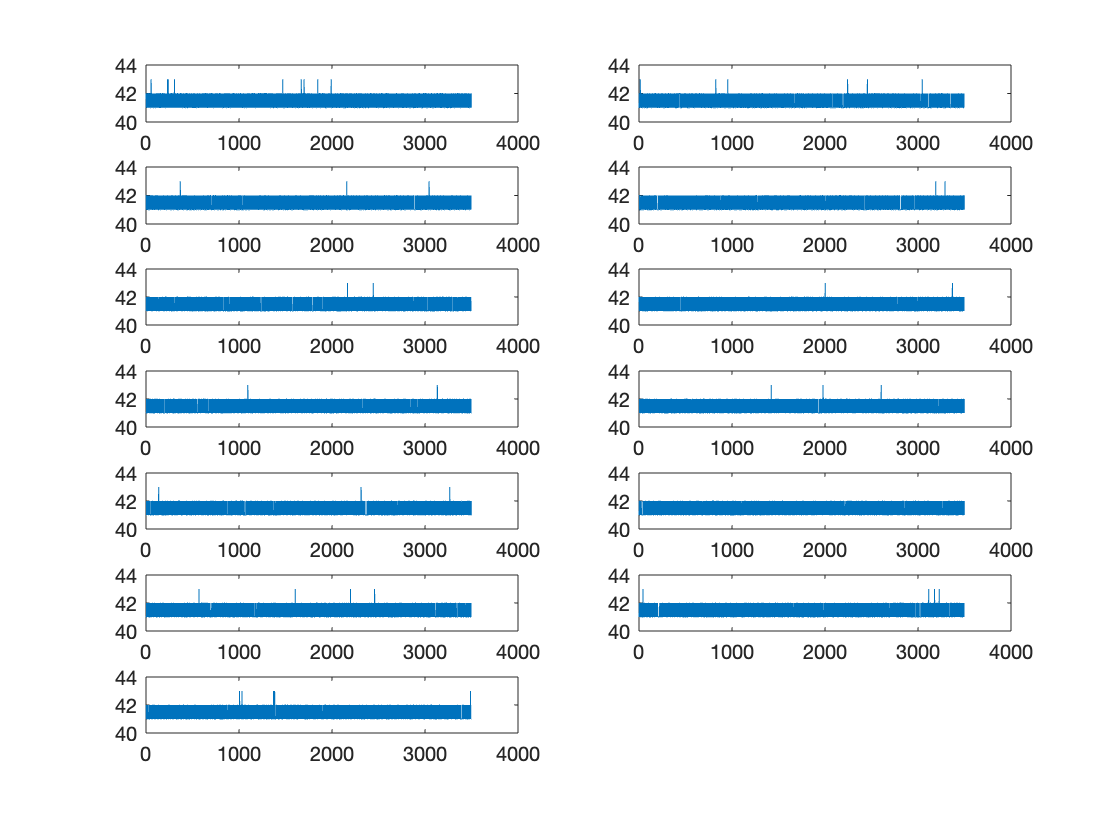

first_acq=10;

for i=1:size(Dark_hours,2)
    subplot(ceil(size(Dark_hours,2)/2),2,i)
    eval(['plot(max_points_',num2str(Dark_hours(i)-first_acq+1),')'])
    ylim([40 44])
end

[n, xout]=hist(max_points_all)

n =        35573           0         181           0       23635           0           0           1           0          54


xout =    41.1000   41.3000   41.5000   41.7000   41.9000   42.1000   42.3000   42.5000   42.7000   42.9000


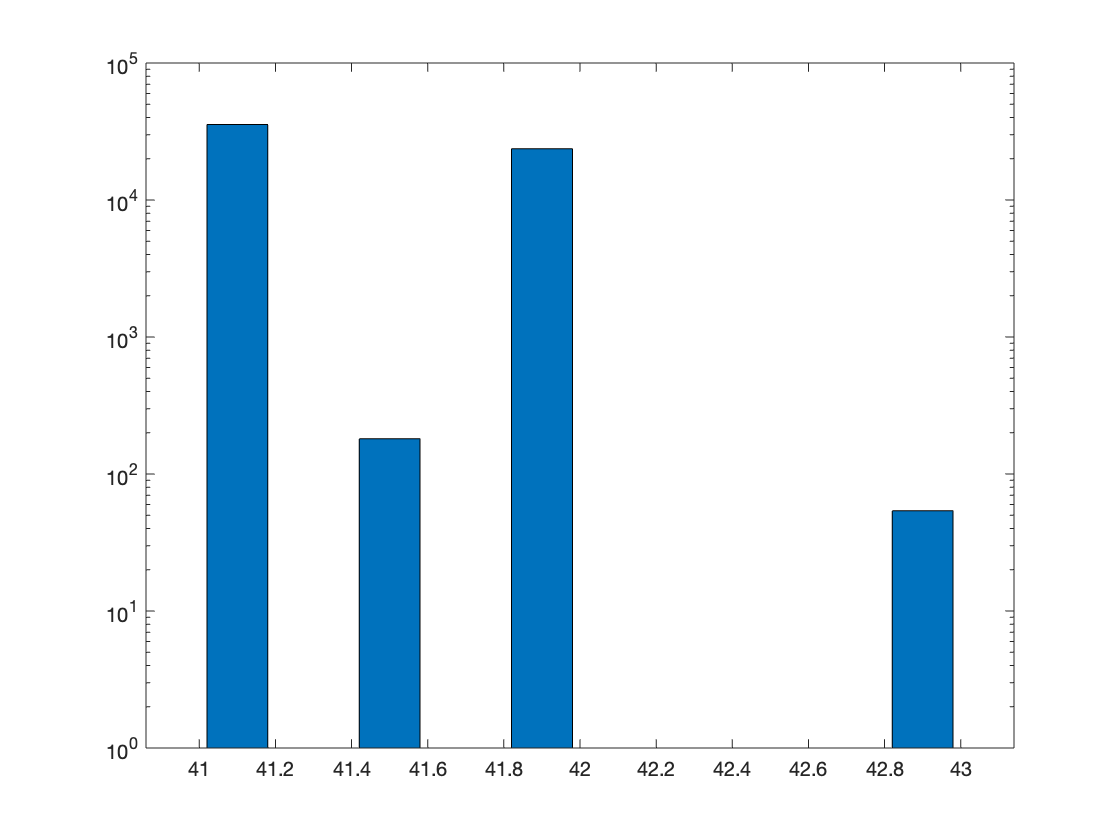

figure
bar(xout, n)
set(gca,'YScale','log')

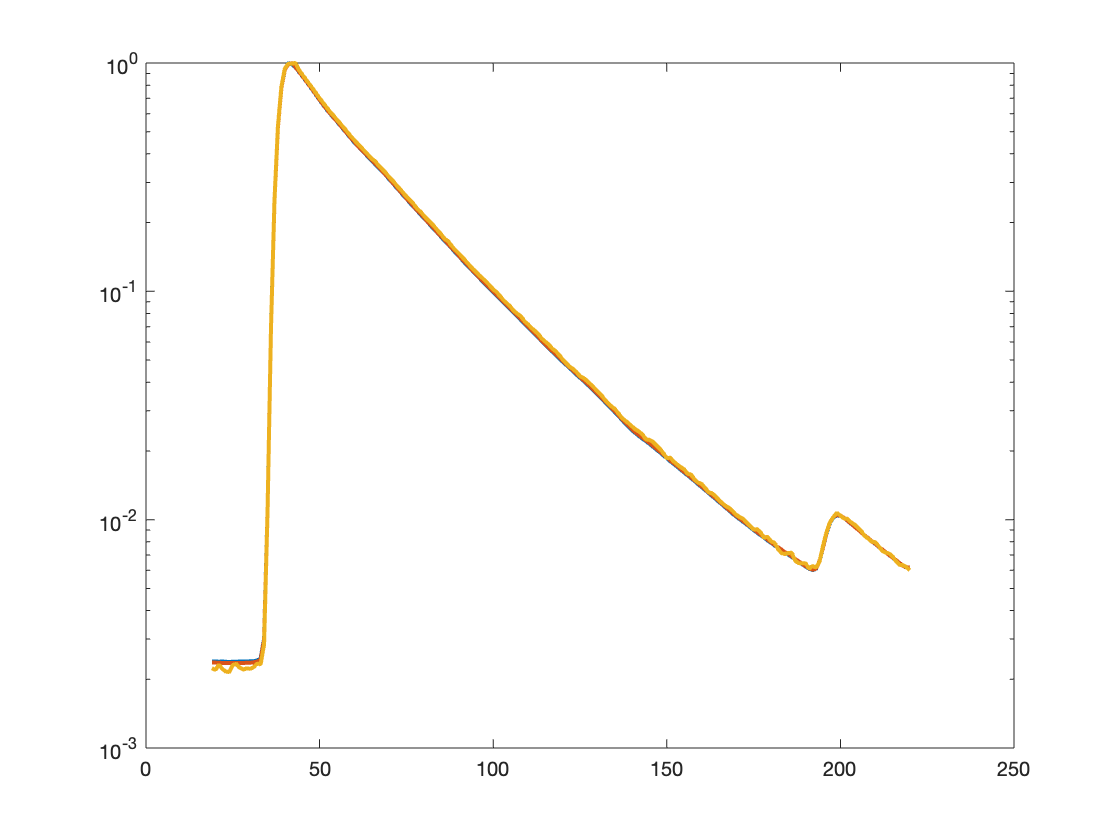

histograms_40=histograms_40';
histograms_41=histograms_41';
histograms_42=histograms_42';
histograms_43=histograms_43';

figure
% semilogy(mean(histograms_40(:,1:220)),'LineWidth',2)
% hold on
semilogy(mean(histograms_41(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_42(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_43(:,1:220)),'LineWidth',2)

ExperimentName='20220213_1612_SW_001'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[11 12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     11    12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];



max_points_all=[];
photoncount_all=[];
histograms_39=[];
histograms_40=[];
histograms_41=[];
histograms_42=[];
histograms_43=[];

for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'h_20220228.mat'];
    load(filename)
    eval(['max_points_',num2str(i),'=zeros(1, size(lifetime_histograms, 2));'])
    for j=1:size(lifetime_histograms, 2)
        single_histogram=lifetime_histograms(:,j);
        eval(['max_points_',num2str(i),'(',num2str(j),')=mean(find(single_histogram==max(single_histogram)));'])
        
        if find(single_histogram==max(single_histogram))==39
            histograms_39=[histograms_39 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==40
            histograms_40=[histograms_40 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==41
            histograms_41=[histograms_41 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==42
            histograms_42=[histograms_42 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==43
            histograms_43=[histograms_43 single_histogram/max(single_histogram)];
        end
    end
    eval(['max_points_all=[max_points_all max_points_',num2str(i),'];'])
    photoncount_all=[photoncount_all photoncount'];
%     figure
%     eval(['histogram(max_points_',num2str(i),')'])
    
end

save([ExperimentName,'_peaks.mat'])


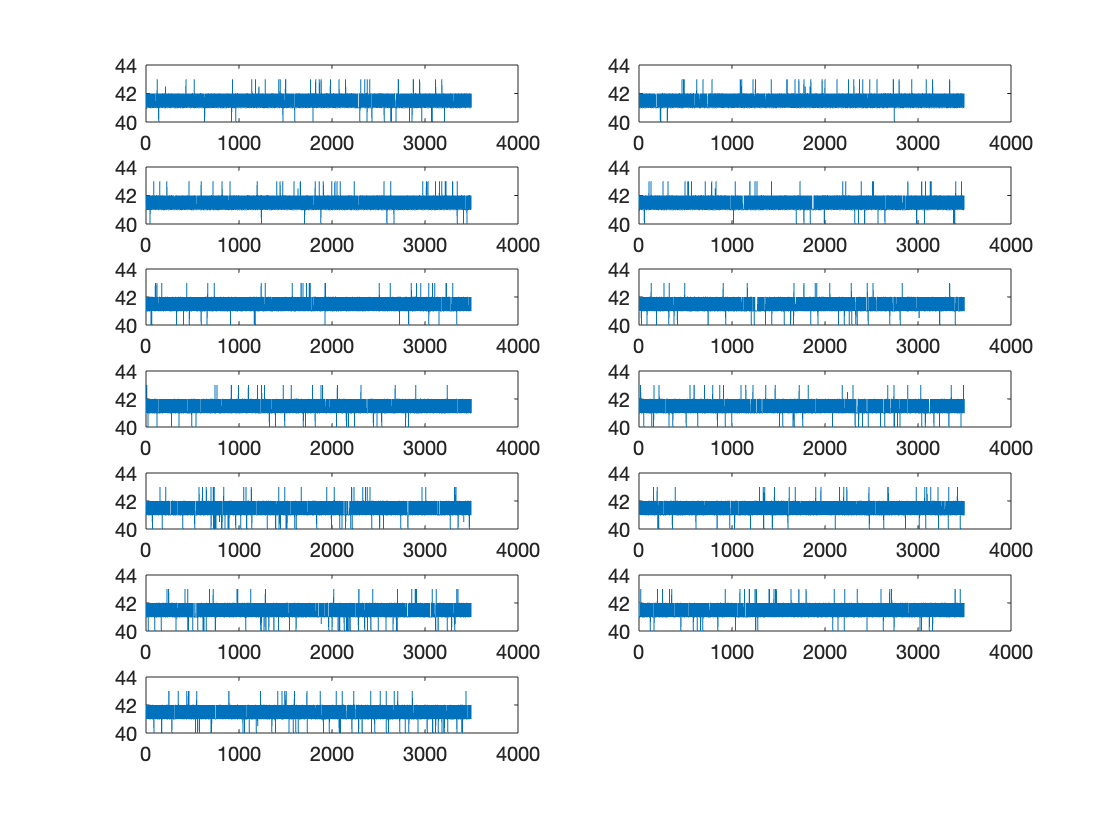

for i=1:size(Dark_hours,2)
    subplot(ceil(size(Dark_hours,2)/2),2,i)
    eval(['plot(max_points_',num2str(Dark_hours(i)-FirstAcq+1),')'])
    ylim([40 44])
end

[n, xout]=hist(max_points_all)

n =          807          18           0       55677         310           0       26454           0          14         648


xout =    40.1500   40.4500   40.7500   41.0500   41.3500   41.6500   41.9500   42.2500   42.5500   42.8500


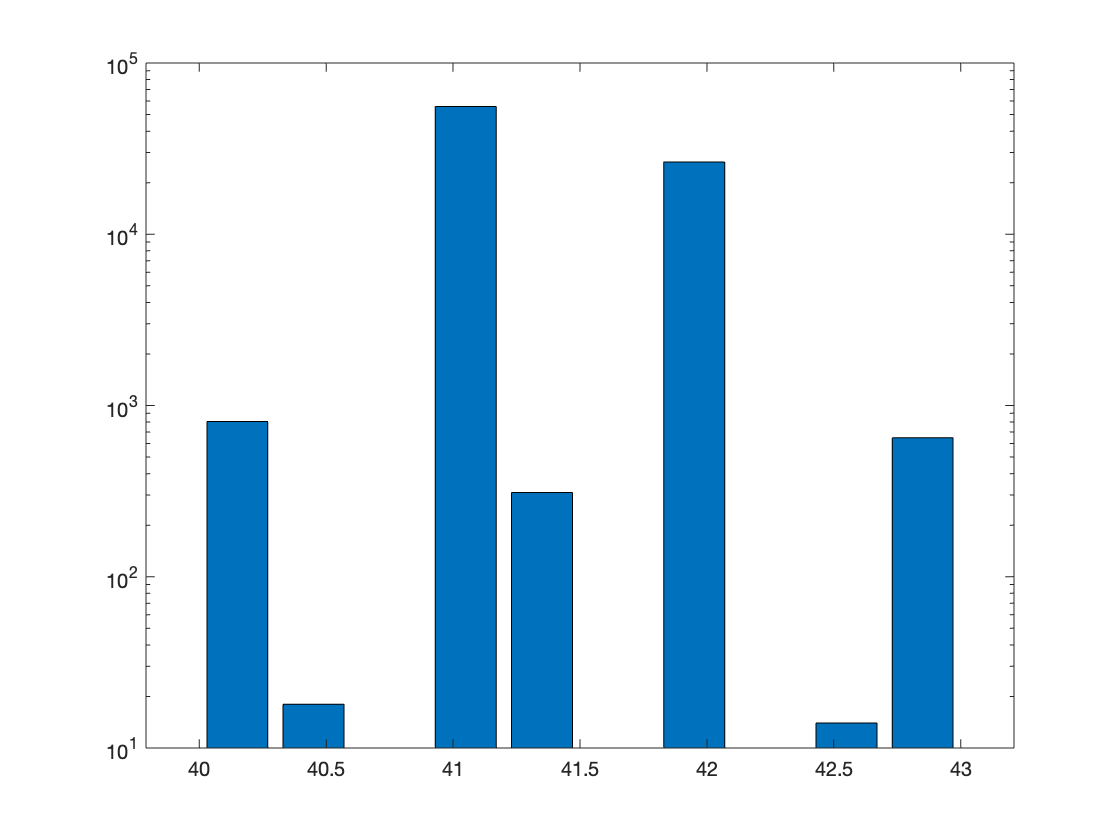

figure
bar(xout, n)
set(gca,'YScale','log')

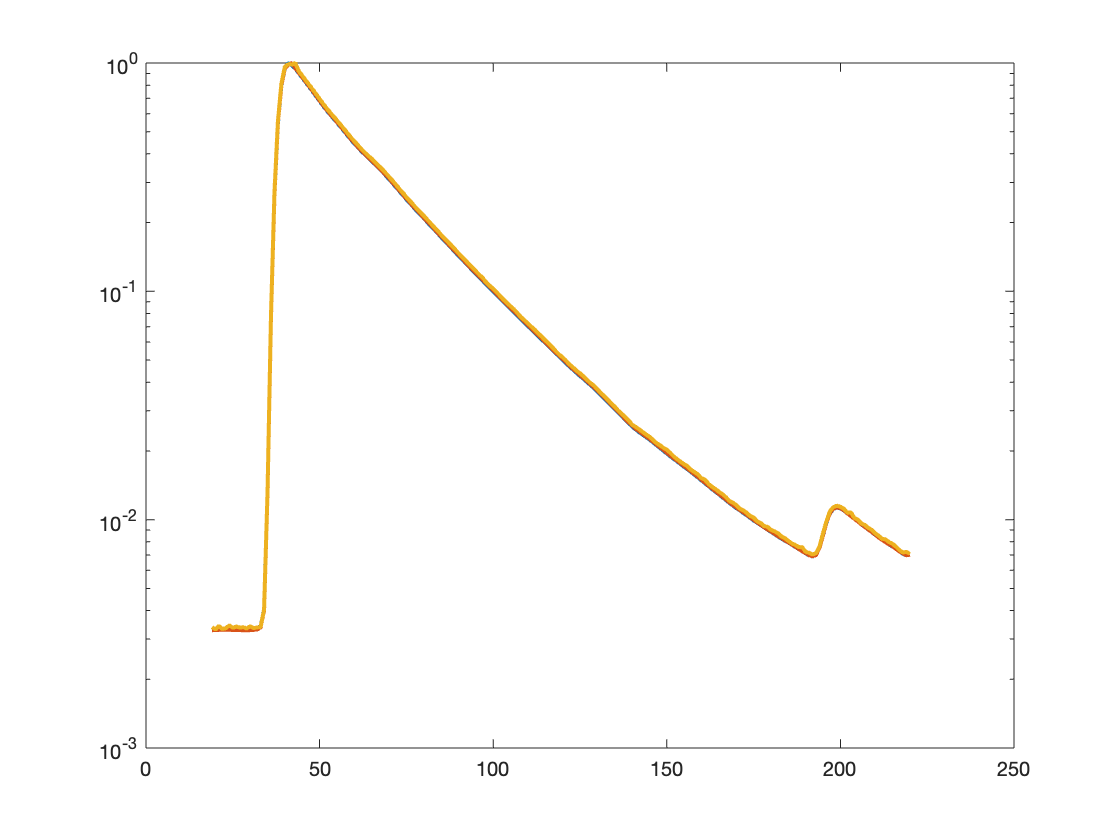

histograms_40=histograms_40';
histograms_41=histograms_41';
histograms_42=histograms_42';
histograms_43=histograms_43';

figure
% semilogy(mean(histograms_40(:,1:220)),'LineWidth',2)
% hold on
semilogy(mean(histograms_41(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_42(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_43(:,1:220)),'LineWidth',2)

ExperimentName='20220301_1612_SW_003'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 16; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];

max_points_all=[];
photoncount_all=[];
histograms_39=[];
histograms_40=[];
histograms_41=[];
histograms_42=[];
histograms_43=[];

for i=1:number_of_acq
    filename=[analysis_name,num2str(i),'h_20220304_flexiblepeak.mat'];
    load(filename)
    eval(['max_points_',num2str(i),'=zeros(1, size(lifetime_histograms, 2));'])
    for j=1:size(lifetime_histograms, 2)
        single_histogram=lifetime_histograms(:,j);
        eval(['max_points_',num2str(i),'(',num2str(j),')=mean(find(single_histogram==max(single_histogram)));'])
        
        if find(single_histogram==max(single_histogram))==39
            histograms_39=[histograms_39 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==40
            histograms_40=[histograms_40 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==41
            histograms_41=[histograms_41 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==42
            histograms_42=[histograms_42 single_histogram/max(single_histogram)];
        end
        
        if find(single_histogram==max(single_histogram))==43
            histograms_43=[histograms_43 single_histogram/max(single_histogram)];
        end
    end
    eval(['max_points_all=[max_points_all max_points_',num2str(i),'];'])
    photoncount_all=[photoncount_all photoncount'];
%     figure
%     eval(['histogram(max_points_',num2str(i),')'])
    
end

save([ExperimentName,'_peaks.mat'])


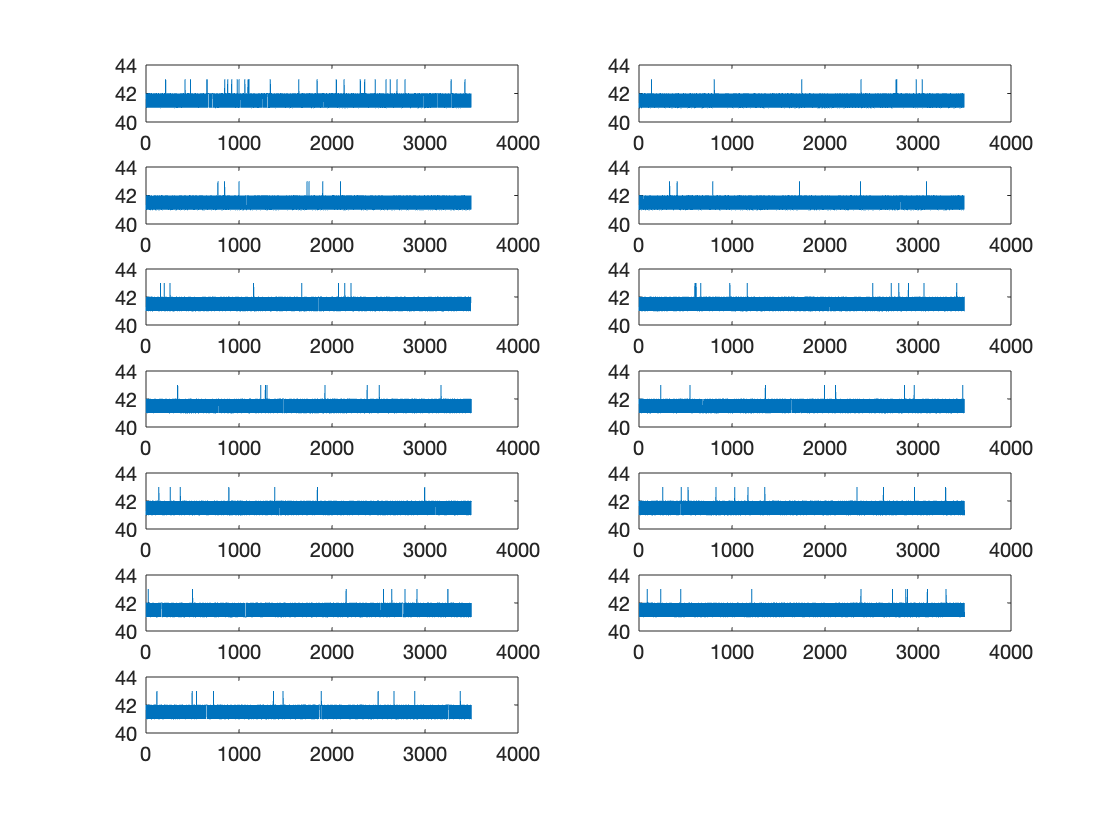

for i=1:size(Dark_hours,2)
    subplot(ceil(size(Dark_hours,2)/2),2,i)
    eval(['plot(max_points_',num2str(Dark_hours(i)-FirstAcq+1),')'])
    ylim([40 44])
end

[n, xout]=hist(max_points_all)

n =        25290           0         146           0       30348           0           0           0           0         174


xout =    41.1000   41.3000   41.5000   41.7000   41.9000   42.1000   42.3000   42.5000   42.7000   42.9000


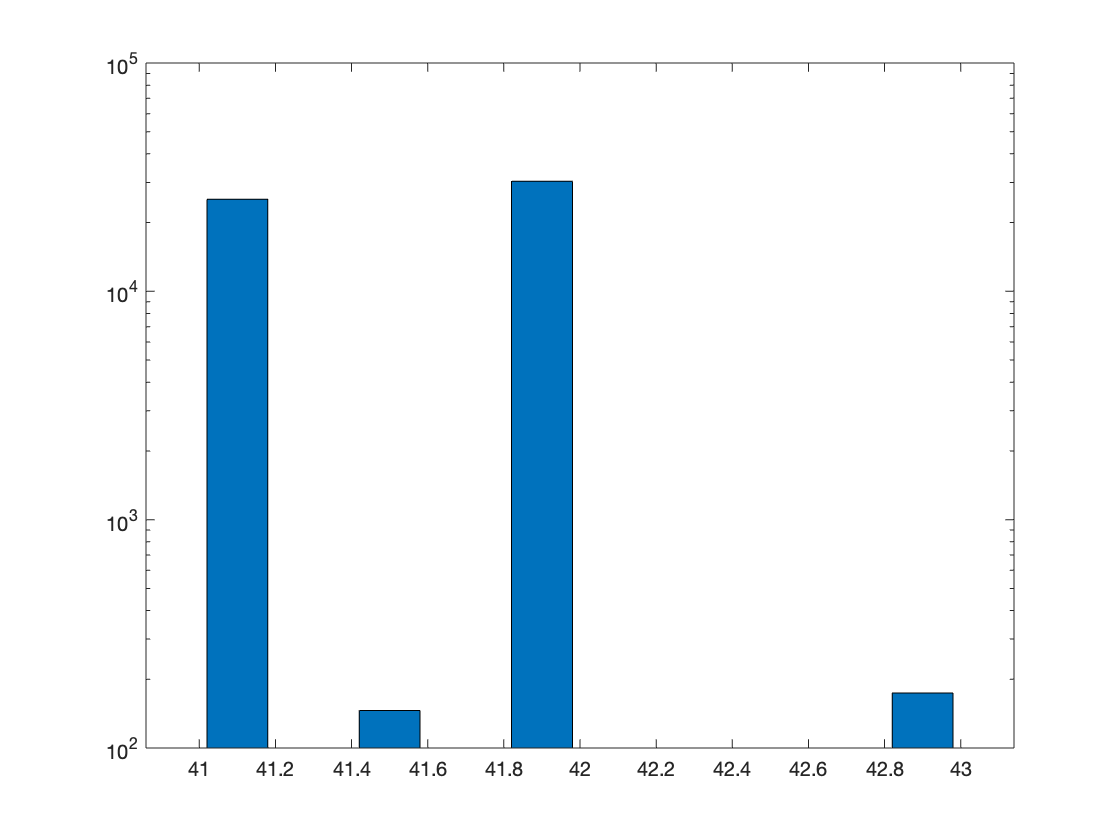

figure
bar(xout, n)
set(gca,'YScale','log')

histograms_40=histograms_40';
histograms_41=histograms_41';
histograms_42=histograms_42';
histograms_43=histograms_43';

figure
% semilogy(mean(histograms_40(:,1:220)),'LineWidth',2)
% hold on
semilogy(mean(histograms_41(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_42(:,1:220)),'LineWidth',2)
hold on
semilogy(mean(histograms_43(:,1:220)),'LineWidth',2)




